# Señales y sistemas

## Señales continuas y discretas

a


$${\frac{d}{\textrm{dx}}e}^x =e^x$$


$sen(\omega\tau)$,

Señal continua:= x(t)    función continua

Señal discreta:= x[n]    muestras de una función continua

## Handles Vs Symbolic

syms t

%Variable simbolica
y_symb = cos(t)

$$y\_symb = \cos\left(t\right)$$


%Function handle
y_fh = @(t) cos(t)

y_fh = function_handle with value:
    @(t)cos(t)





%Diferencia entre variables simbolicas y function handles
y_fh([5 8 10]) %Se evaluan directamente

ans =     0.2837   -0.1455   -0.8391


%y_symb([5 8 10]) %Error: NO se evaluan directamente
subs(y_symb,t,[5 8 10])

$$ans = \left(\begin{array}{ccc} \cos\left(5\right) & \cos\left(8\right) & \cos\left(10\right) \end{array}\right)$$


%Se puede hacer algebra con variables simbolicas
y_3 = y_symb + sin(t) + exp(-t)

$$y\_3 = {\mathrm{e}}^{-t}+\cos\left(t\right)+\sin\left(t\right)$$

diff(y_3)

$$ans = \cos\left(t\right)-{\mathrm{e}}^{-t}-\sin\left(t\right)$$

int(y_3,[0 1])

$$ans = \sin\left(1\right)-{\mathrm{e}}^{-1}-\cos\left(1\right)+2$$

int(y_3,t)

$$ans = -{\mathrm{e}}^{-t}-\sqrt{2}\,\cos\left(t+\frac{\pi }{4}\right)$$

%y_fh + y_fh %Error: No se pueden hacer operaciones con function handle
y_3_fh = matlabFunction(y_3) %convierte simbolicas en fh

y_3_fh = function_handle with value:
    @(t)exp(-t)+cos(t)+sin(t)


y_3_fh([5 8 10])

ans =    -0.6685    0.8442   -1.3830


## Continuas VS Discretas

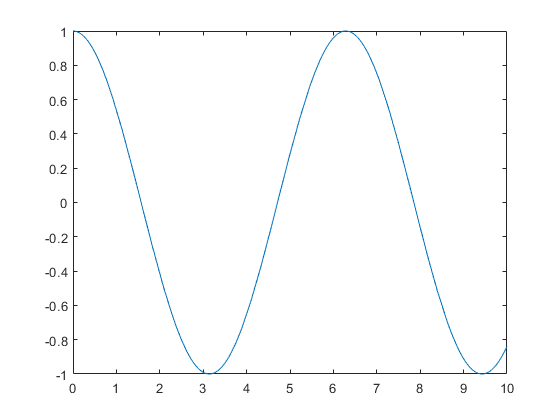

%fplot es para funciones simbolicas
%y tambien para "function handles"
figure
fplot(y_symb,[0 10])


figure
fplot(y_fh,[0 10])


% ";" suprime la salida en los resultados
t_disc = 0:10

t_disc =      0     1     2     3     4     5     6     7     8     9    10


t_disc = 0:10;

y_disc = y_fh(t_disc)

y_disc =     1.0000    0.5403   -0.4161   -0.9900   -0.6536    0.2837    0.9602    0.7539   -0.1455   -0.9111   -0.8391


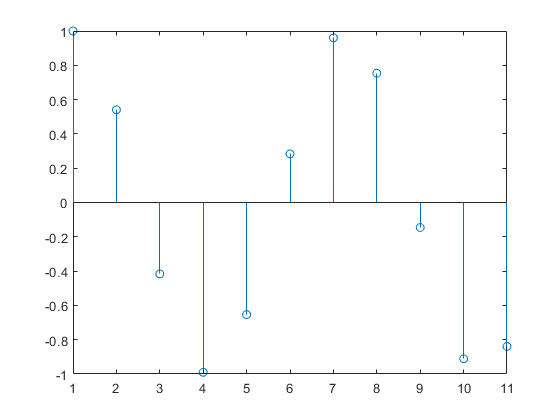


figure
%plot es para muestras o vectores
stem(y_disc)

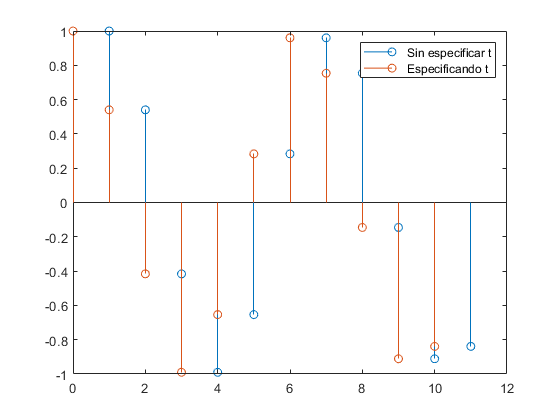


figure
stem(y_disc)
hold on
%stem es para muestras o vectores
stem(t_disc,y_disc)
hold off
legend("Sin especificar t", "Especificando t")


t_disc = 0:0.1:10

t_disc =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


y_disc = y_fh(t_disc)

y_disc =     1.0000    0.9950    0.9801    0.9553    0.9211    0.8776    0.8253    0.7648    0.6967    0.6216    0.5403    0.4536    0.3624    0.2675    0.1700    0.0707   -0.0292   -0.1288   -0.2272   -0.3233   -0.4161   -0.5048   -0.5885   -0.6663   -0.7374   -0.8011   -0.8569   -0.9041   -0.9422   -0.9710   -0.9900   -0.9991   -0.9983   -0.9875   -0.9668   -0.9365   -0.8968   -0.8481   -0.7910   -0.7259   -0.6536   -0.5748   -0.4903   -0.4008   -0.3073   -0.2108   -0.1122   -0.0124    0.0875    0.1865


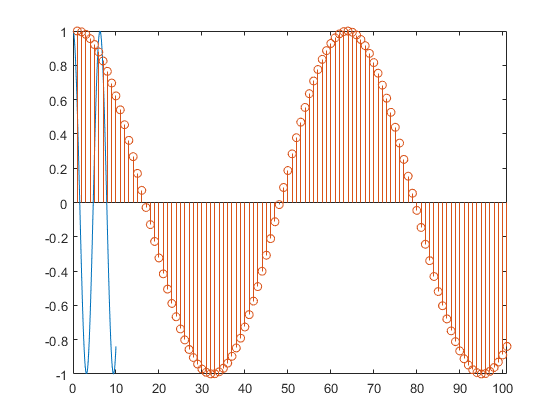


figure
fplot(y_fh,[0 10])
hold on
stem(t_disc,y_disc)
hold off

legend("Señal continua x(t)","Señal discreta x[t]")

figure
fplot(y_fh,[0 10])
hold on
stem(y_disc)
hold off
legend("Señal continua x(t)","Señal discreta x[n]")

## Ejercicio

syms r

x_fh1 = @(r) 3*exp(0.4*r)

x_fh1 = function_handle with value:
    @(r)3*exp(0.4*r)


y_fh1 = @(r) 2*exp(-0.9*r)

y_fh1 = function_handle with value:
    @(r)2*exp(-0.9*r)


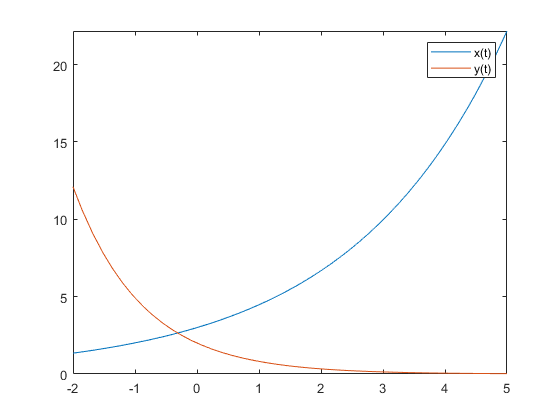


figure
fplot(x_fh1,[-2 5])
hold on
fplot(y_fh1,[-2 5])
hold off
legend("x(t)","y(t)")

## Ejercicio 2

syms s
x = cos(s) + sin(3*s)

$$x = \sin\left(3\,s\right)+\cos\left(s\right)$$

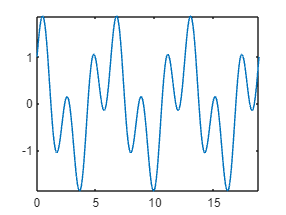


figure
fplot(x,[0 6*pi])

## Formas de onda básicas

syms t
a =3.2 ;
b =3.3 ;
t0 =5.1 

t0 = 5.1000

tf =69.4

tf = 69.4000

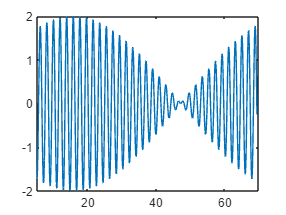


x(t) = cos(a*t) + sin(b*t);

figure
fplot(x,[t0 tf])

## Ejercicio 3

syms t
theta = 5

theta = 5

omega_0 = 50

omega_0 = 50

C =1

C = 1

r =-3.6

r = -3.6000


x1(t) = C*exp(r*t)*cos(omega_0*t + theta)

$$x1(t) = {\mathrm{e}}^{-\frac{18\,t}{5}}\,\cos\left(50\,t+5\right)$$

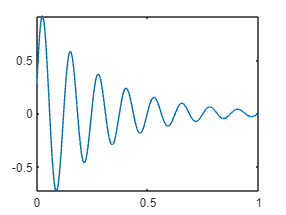


figure
fplot(x1,[0,1])

## Gráfica cos + sin

0:0.01:10

ans =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


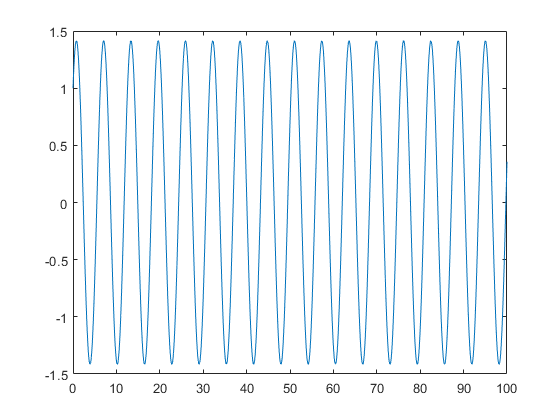

x=sin(t)+cos(t);
figure
plot(t,x)